# Unit 1 - Sem 3 - 22MAT220 

# Mathematics for Computing

#### To be added

Nuclear norm(Schatten-0) (WIP)

Weighted $L_1$ and $L_2$ norm 

Schatten-p norm (p=2 is Frobenius norm )

$L_1$ regularization or Lasso Regression, 

(Least Absolute Shrinkage and Selection Operator)

$L_2$ regularization or Ridge Regression or Tikhonov regularization, (named for Andrey Tikhonov)

Basis pursuit (solution to system of linear equation with minimal $\ell_1$ norm)

Basis Pursuit Denoising ($\ell_1$ norm penalized least squares)

Total Variation

Consensus

SVM

Derivation of Pseudoinverse of A 

SALSA (Split Augmented Lagrangian Shrinkage Algorithm)

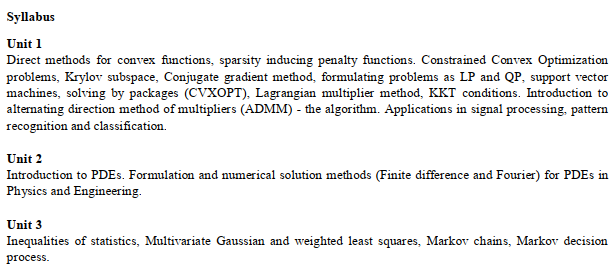

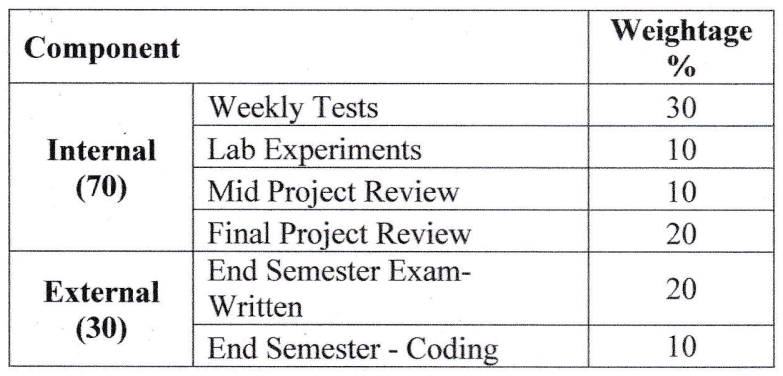

# Notation

$x\neq \mathbf{x}$ ,$x \in R$, $\mathbf{x} \in R^n$

$x$ is a variable that can take a real value.

$\mathbf{x}$ is a vector of $n$ variables / unknowns, $x_1, x_2 , \cdots x_n$. Think of it as an ordered array of $n$ variables that can take real values.

$\underset{\mathbf{x}}{\mathrm{argmin}} \space f_1(\mathbf{x})$  **Where** is the minimum of the function

$\underset{\mathbf{x}}{\mathrm{min}} \space f_1(\mathbf{x})$        **What** is the minimum value of the function

$\underset{\mathbf{x}}{\mathrm{argmax}} \space f_2(\mathbf{x})$  **Where** is the maximum of the function

$\underset{\mathbf{x}}{\mathrm{max}} \space f_2(\mathbf{x})$        **What** is the maximum value of the function

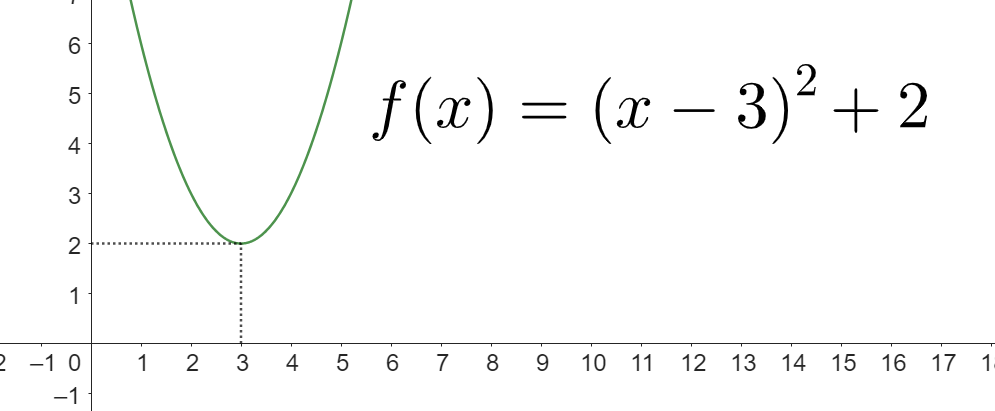

#### Examples : Function of 1 variable , $x$


$$2=\underset{x}{\mathrm{argmin}} \space \left(f(x)=(x-2)^2+7)$$



$$7=\underset{x}{\mathrm{min}} \space (f(x)=(x-2)^2+7)$$



$$3=\underset{x}{\mathrm{argmax}} \space (f(x)=20-(x-3)^2)$$



$$20=\underset{x}{\mathrm{max}} \space (f(x)=20-(x-3)^2)$$


#### Examples : Function of more than 1 variable, $\mathbf{x}$

$\left[\matrix{0\cr 0}\right]=\underset{\mathbf{x}}{\mathrm{argmin}}\space f(\mathbf{x})=\mathbf{x}^TQ\mathbf{x}+2$, $Q = \left[\matrix{1 & 0 \cr 0 &3}\right]$


$$f(x,y)=x^2+3y^2$$

$$=\left[\matrix{x & y}\right]\left[\matrix{1 & 0 \cr 0 &3}\right]\left[\matrix{x\cr y}\right]+2$$



$$2=\underset{\mathbf{x}}{\mathrm{min}}\space f(\mathbf{x})=\mathbf{x}^TQ\mathbf{x}+2$$


$\left[\matrix{0\cr 0}\right]=\underset{\mathbf{x}}{\mathrm{argmax}}\space f(\mathbf{x})=\mathbf{x}^TQ\mathbf{x}-4$, $Q = \left[\matrix{-1 & 0 \cr 0 &-3}\right]$


$$f(x,y)=-x^2-3y^2-4$$

$$=\left[\matrix{x & y}\right]\left[\matrix{-1 & 0 \cr 0 &-3}\right]\left[\matrix{x\cr y}\right]-4$$



$$-4=\underset{\mathbf{x}}{\mathrm{max}}\space f(\mathbf{x})=\mathbf{x}^TQ\mathbf{x}-4$$


# Constrained Convex Optimization problem

The general form of a constrained convex optimization problem is

${\underset{\mathbf{x}}{\mathrm{min}}\space f(\mathbf{x})}$ subject to the constraint $\mathbf{x} \in \mathbf{C}$

where $f$ is a convex function and $\mathbf{C}$ is a convex set.

# $L_0$ norm

(not strictly a norm function)

**Understanding the **$L_0$** Norm: Counting the Non-Zero**

The $L_0$ norm of a vector, denoted as $\|x\|_0$  is defined as the number of non-zero elements in that vector. For instance, for the vector $\mathbf{x}=\left[\matrix{ 0\cr 5\cr 0\cr -2\cr 3} \right]$ , the $L_0$ norm $\|x\|_0$ is $3$, as there are three non-zero elements $5, -2$ and $3$.

**Mathematical Definition:**

For a vector $\mathbf{x} \in R^n$, the $L_0$ norm is given by:


$$\|x\|_0=\sum_{i=1}^n|x_i|^0$$


where $|x_i|^0 = 1$ if $x_i \neq 0$ and $0$ if $x_i=0$.

# $L_1$ norm

is the sum of the absolute values of each elements of $\mathbf{x}$. 


$$\|\mathbf{x}\|_1=\sum_{i=1}^n|x_i|$$


**Unit norm ball in 2 dimension**


$$\mathbf{x} \in R^2$$


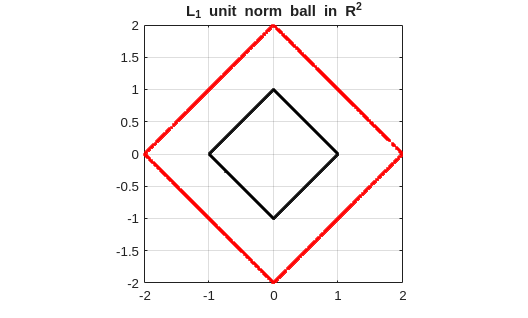

clearvars
x = rand(2,2500)-0.5;
x = x./sum(abs(x));
x2 = 2*x;
plot(x(1,:),x(2,:),'k.');hold on
plot(x2(1,:),x2(2,:),'r.');hold off
axis equal
title("L_1 unit norm ball in R^2")
grid on
xlim([-2 2])
ylim([-2 2])

**Unit norm ball in 3 dimension**


$$\mathbf{x} \in R^3$$


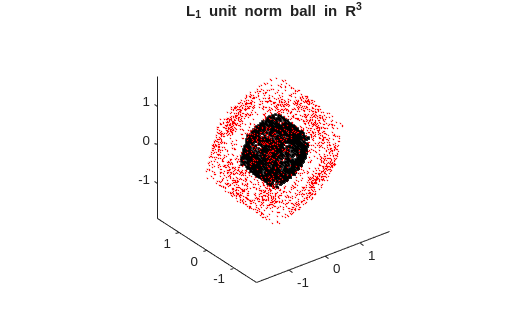

clearvars
x = rand(3,2500)-0.5;
x = x./sum(abs(x));
plot3(x(1,:),x(2,:),x(3,:),'k.');hold on
axis equal
title("L_1 unit norm ball in R^3")

x2 = 2*x;
plot3(x2(1,:),x2(2,:),x2(3,:),'r.',MarkerSize=0.5);
hold off


$$y=\|\mathbf{x}\|_1$$


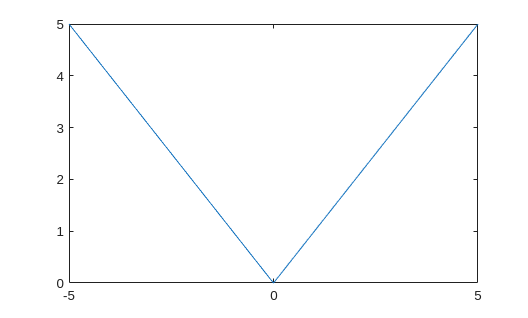

x1 = single(-5:0.2:5);
y = abs(x1);
plot(x1,y)

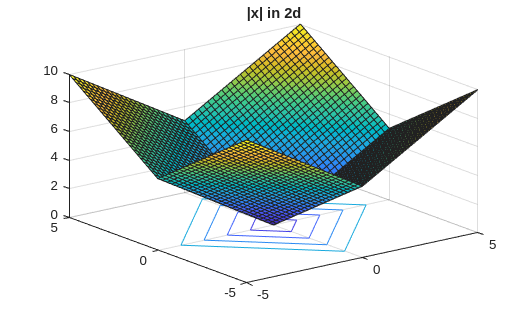

clearvars
x1 = single(-5:0.2:5);
x2 = x1;
[X1,X2] = meshgrid(x1,x2);
Z1 = abs(X1)+abs(X2);
surf(X1,X2,Z1);hold on
contour(X1,X2,Z1,1:4); hold off
title("|x| in 2d")

$L_1$ norm ball in 3d (function of 3 variables)

x = single(rand(5e3,3)-0.5);
x = x./sum(abs(x),2);
size(x)

ans =         5000           3


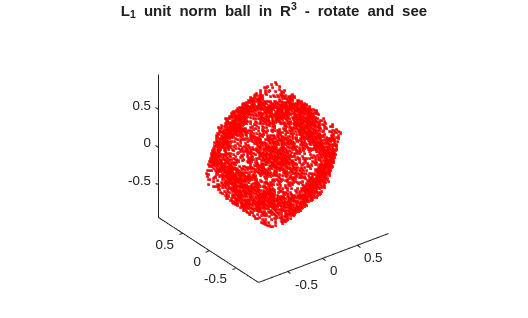

plot3(x(:,1),x(:,2),x(:,3),'r.')
axis equal
title('L_1 unit norm ball in R^3 - rotate and see')

# $L_2$ norm

is the square root of the sum of the squares of each values of $\mathbf{x}$. 

$\|\mathbf{x}\|_2^2=\sum_{i=1}^nx_i^2$ square of the $L_2$ norm

$L_2$ norm $= \sqrt{\sum_{i=1}^nx_i^2}$

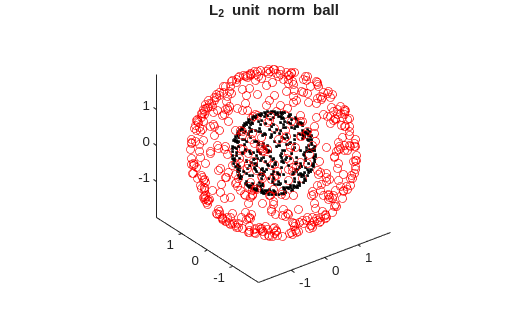

x = rand(3,500)-0.5;
x = x./(sqrt(sum(x.^2)));

plot3(x(1,:),x(2,:),x(3,:),'k.');hold on
axis equal
title("L_2 unit norm ball")
x = 2*x./(sqrt(sum(x.^2)));
plot3(x(1,:),x(2,:),x(3,:),'ro');hold off

# $L_\infty$ norm

is the maximum of the absolute values of $\mathbf{x}$. 


$$\|\mathbf{x}\|_\infty=\max \{|x_i|\}$$



$$\mathbf{x} \in R^2$$


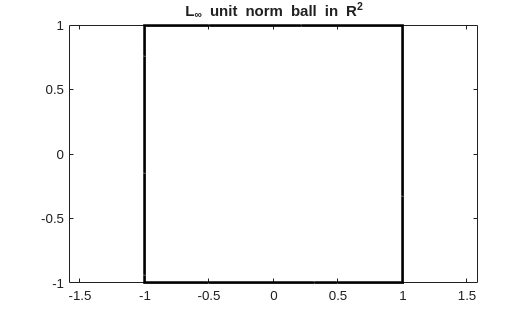

x = rand(2,2500)-0.5;
x = x./(max(abs(x)));
plot(x(1,:),x(2,:),'k.')
axis equal
title("L_\infty unit norm ball in R^2")


$$\mathbf{x} \in R^3$$


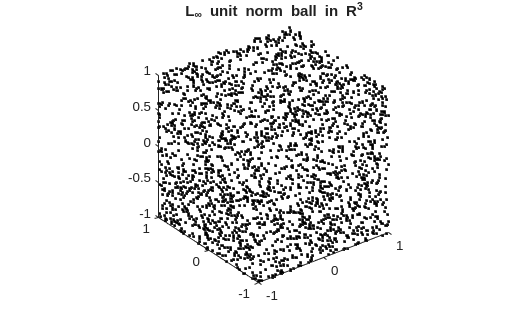

x = rand(3,2500)-0.5;
x = x./(max(abs(x)));
plot3(x(1,:),x(2,:),x(3,:),'k.')
axis equal
title("L_\infty unit norm ball in R^3")

# $L_p$ norm

is defined as  


$$\|\mathbf{x}\|_p = \left(\sum_{i=1}^n |x_i|^p\right)^{\frac{1}{p}}$$


with $1\leq p \lt \infty$


$$\mathbf{x} \in R^2$$


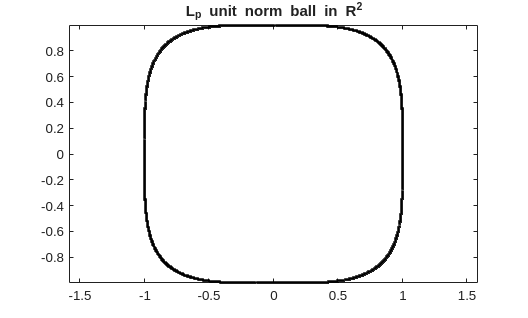

x = rand(2,2500)-0.5;
p = 4;
x = x./power(sum(abs(x).^p),1/p);
plot(x(1,:),x(2,:),'k.')
axis equal
title("L_p unit norm ball in R^2")


$$\mathbf{x} \in R^3$$


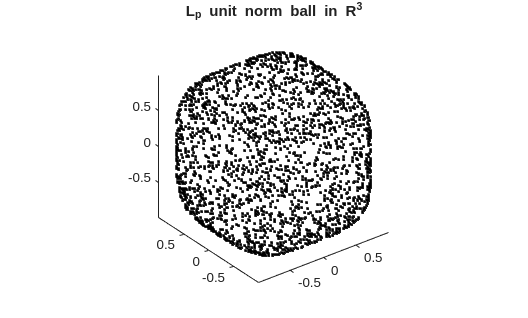

x = rand(3,2500)-0.5;
p = 4;
x = x./power(sum(abs(x).^p),1/p);
plot3(x(1,:),x(2,:),x(3,:),'k.')
axis equal
title("L_p unit norm ball in R^3")

# Interesting facts

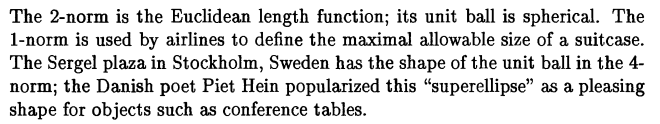

# Right inverse

If all the rows of a matrix $A\in R^{m \times n}$ are independent, then rank of $AA^T$ is $m$ and hence $AA^T$ is invertible. 

So $AA^T(AA^T)^{-1}=I_r$ .

$A^+ = A^T(AA^T)^{-1}$ is the right inverse of $A$.

#### Right inverse is not unique.

Consider a matrix $A_{m \times n}$ where $m \lt n$, and $A$ has full row rank. If $B$ is a right inverse ( $AB=I_m$ ), then for any matrix $C$ whose columns are in the RNS of $A$ (i.e., $AC=0$), the matrix $(B+C)$ will also be a right inverse: $A(B+C)=AB+AC=I_m+0=I_m$.

Similar to the left inverse, among the infinitely many right inverses, there is a unique one called the Moore-Penrose pseudoinverse ( $A^\dagger$). For a matrix $A$ with full row rank, the pseudoinverse is given by $A^\dagger=A^T(AA^T)^{-1}$. This is the unique right inverse that minimizes the Frobenius norm of $B$-- Check this property !.

$A\mathbf{x}=\mathbf{b}$ if all the rows of $A$ are independent, then $\mathbf{x} = A^+\mathbf{b}$ is the least norm solution , where $A^+$ is the right inverse of $A$

# Left inverse

If all the columns of a matrix $A\in R^{m \times n}$ are independent, then the rank of $A^TA$ is $n$ and hence $A^TA$ is invertible. 

So $(A^TA)^{-1}A^TA=I_r$

$A^+ =(A^TA)^{-1}A^T$ is the left inverse of $A$.

#### Left inverse is not unique.

Consider a matrix $A_{m \times n}$ where $m \gt n$ and $A$ has full column rank. If $B$ is a left inverse ( $BA=I_n$ ), then for any matrix $C$ whose rows are in the LNS of $A$ (i.e., $CA=0$), the matrix ( $B+C$) will also be a left inverse: $(B+C)A=BA+CA=I_n+0=I_n$.

Among the infinitely many left inverses, there is a unique one called the Moore-Penrose pseudoinverse (often denoted $A^\dagger$). For a matrix $A$ with full column rank, the pseudoinverse is given by $A\dagger=(A^TA)^{-1}A^T$ . This particular left inverse has special properties, such as minimizing the Frobenius norm of $B$. -- Check this property !

$A\mathbf{x}=\mathbf{b}$ if all the columns of $A$ are independent, then $\mathbf{x} = A^+\mathbf{b}$ is the only solution possible, where $A^+$ is the left inverse of $A$

# Derivation of Pseudoinverse of A using projection

Starting from the $CR$ decomposition of $A$

$A\mathbf{x}\approx \mathbf{y}$   Project $\mathbf{y}$ onto the column space of $A$.

$CR\mathbf{x}=CC^+\mathbf{y}$   Pre multiplying by $C^+$

$C^+CR\mathbf{x}=C^+CC^+\mathbf{y}$ , But $C^+C = I_r$ where $r$ is the rank of $A$ and $C$

$\therefore R\mathbf{x}=C^+\mathbf{y}$  Pre multiplying by $R^+$

$R^+R\mathbf{x} = R^+C^+\mathbf{y}$ , $R^+R$ is the projection operator for the row space of $A$ and hence $R^+R\mathbf{x}$ is the row space solution vector $\mathbf{x}_r$.


$$\therefore \mathbf{x}_r=R^+C^+\mathbf{y}$$


ie., $A^+ = R^+C^+$

# PseudoInverse

$A =CR$, where $A \in \mathbf{R}^{m \times n}$, $C \in \mathbf{R}^{m \times r}$, $R \in \mathbf{R}^{r \times n}$

rank of $C=$ rank of $R=r$


$$A^+=R^+C^+$$

$$=R^T(RR^T)^{-1} \times (C^TC)^{-1}C^T$$



$$=R^T(C^TCRR^T)^{-1}C^T$$



$$=R^T(C^TAR^T)^{-1}C^T$$


# Derivation of ADMM

Consider the optimization problem 

$\underset{\mathbf{x}}{\mathrm{argmin}}f(\mathbf{x})$, $\mathbf{x} \in R^n$

We decompose the multivariate function into 2 functions $f$ and $g$.


$$\underset{\mathbf{x}}{\mathrm{argmin}}f(\mathbf{x})+g(\mathbf{x})$$


This unconstrained optimization problem is converted to constrained by introducing the surrogate variable $\mathbf{z} \in R^n$ with the constraints $\mathbf{x}-\mathbf{z}=\mathbf{0}$.

$\underset{\mathbf{x}}{\mathrm{argmin}}f(\mathbf{x})+g(\mathbf{z})$ subject to the constraints $\mathbf{x}-\mathbf{z}=\mathbf{0}$ 

The Lagrangian function for this problem is 

$L(\mathbf{x},\mathbf{z},\mathbf{\lambda})=f(\mathbf{x})+g(\mathbf{z})+\mathbf{\lambda}^T(\mathbf{x}-\mathbf{z})$, $\mathbf{\lambda} \in R^n$

To show that the first order optimality conditions are preserved, find the gradient of $L$ with respect to $\mathbf{x}$ and $\mathbf{z}$, equate them to zero and add the two expressions.


$$\frac{\partial L}{\partial \mathbf{x}}=$$

$$\nabla_{\mathbf{x}} f(\mathbf{x})+ \mathbf{\lambda}=\mathbf{0}$$



$$\frac{\partial L}{\partial \mathbf{z}}=$$

$$\nabla_{\mathbf{z}} g(\mathbf{z}) -\mathbf{\lambda}=\mathbf{0}$$


Adding these two we get $\nabla f(\mathbf{x}) + \nabla g(\mathbf{z})=\mathbf{0}$

The augmented Lagrangian is 

$L_\rho(\mathbf{x},\mathbf{z},\mathbf{\lambda)}=f(\mathbf{x})+g(\mathbf{z})+\mathbf{\lambda}^T(\mathbf{x}-\mathbf{z})+\frac{\rho}{2}\|\mathbf{x}-\mathbf{z}\|_2^2$, $\mathbf{x,z,\lambda} \in \mathbf{R}^n$ and $\rho \in \mathbf{R}$ and $\rho \gt 0$

To show that the first order optimality conditions are preserved, find the gradient of $L_\rho$ with respect to $\mathbf{x}$ and $\mathbf{z}$, equate them to zero and add the two expressions.


$$\frac{\partial L}{\partial \mathbf{x}}=$$

$$\nabla f(\mathbf{x})+ \mathbf{\lambda} + \rho(\mathbf{x}-\mathbf{z})=\mathbf{0}$$



$$\frac{\partial L}{\partial \mathbf{z}}=$$

$$\nabla g(\mathbf{z}) -\mathbf{\lambda}-\rho(\mathbf{x}-\mathbf{z})=\mathbf{0}$$


Adding these two we get $\nabla f(\mathbf{x}) + \nabla g(\mathbf{z})=\mathbf{0}$

The minimum location at which the augmented Lagrangian is minimum is computed numerically by updating the variables $\mathbf{x}$,$\mathbf{z}$ and $\mathbf{\lambda}$ in each iteration. The iteration is continued until the desired precision is achieved.

Assume $\mathbf{z}^{(k)}$ and $\mathbf{\lambda}^{(k)}$ are known from the previous iteration.

## 
$$\mathbf{x}^{(k+1)}=$$

$$\underset{\mathbf{x}}{\mathrm{argmin}}\space L_\rho(\mathbf{x},\mathbf{z}^{(k)},\mathbf{\lambda}^{(k)})$$



$$=\underset{\mathbf{x}}{\mathrm{argmin}}\space$$

$$f(\mathbf{x})+g(\mathbf{z}^{(k)})+\mathbf{\lambda}^{(k)T}(\mathbf{x}-\mathbf{z}^{(k)})+\frac{\rho}{2}\|\mathbf{x}-\mathbf{z}^{(k)}\|_2^2$$



$$=\underset{\mathbf{x}}{\mathrm{argmin}}\space$$

$$f(\mathbf{x})+g(\mathbf{z}^{(k)})+\mathbf{\lambda}^{(k)T}\mathbf{x}-\mathbf{\lambda}^{(k)T}\mathbf{z}^{(k)}+\frac{\rho}{2}\|\mathbf{x}-\mathbf{z}^{(k)}\|_2^2$$



$$=\underset{\mathbf{x}}{\mathrm{argmin}}\space$$

$$f(\mathbf{x})+\mathbf{\lambda}^{(k)T}\mathbf{x}+\frac{\rho}{2}\|\mathbf{x}-\mathbf{z}^{(k)}\|_2^2+\underbrace{g(\mathbf{z}^{(k)})-\mathbf{\lambda}^{(k)T}\mathbf{z}^{(k)}}_{constant}$$



$$=\underset{\mathbf{x}}{\mathrm{argmin}}\space$$

$$f(\mathbf{x})+\mathbf{\lambda}^{(k)T}\mathbf{x}+\frac{\rho}{2}\|\mathbf{x}-\mathbf{z}^{(k)}\|_2^2$$



$$=\underset{\mathbf{x}}{\mathrm{argmin}}\space$$

$$f(\mathbf{x})+\mathbf{\lambda}^{(k)T}\mathbf{x}+\frac{\rho}{2}(\mathbf{x}-\mathbf{z}^{(k)})^T(\mathbf{x}-\mathbf{z}^{(k)})$$



$$=\underset{\mathbf{x}}{\mathrm{argmin}}\space$$

$$f(\mathbf{x})+\mathbf{\lambda}^{(k)T}\mathbf{x}+$$

$$\frac{\rho}{2}\left(\mathbf{x}^T\mathbf{x}-2\mathbf{z}^{(k)T}\mathbf{x}+\mathbf{z}^{(k)T}\mathbf{z}^{(k)}\right)$$



$$=\underset{\mathbf{x}}{\mathrm{argmin}}\space$$

$$f(\mathbf{x})$$

$$+\frac{\rho}{2}\left(\mathbf{x}^T\mathbf{x}-2\mathbf{z}^{(k)T}\mathbf{x}+\mathbf{z}^{(k)T}\mathbf{z}^{(k)} +\frac{2}{\rho}\mathbf{\lambda}^{(k)T}\mathbf{x}\right)$$



$$=\underset{\mathbf{x}}{\mathrm{argmin}}\spacef(\mathbf{x})$$

$$+\frac{\rho}{2}\left(\mathbf{x}^T\mathbf{x}-2\mathbf{z}^{(k)T}\mathbf{x}+\mathbf{z}^{(k)T}\mathbf{z}^{(k)} +\frac{2}{\rho}\mathbf{\lambda}^{(k)T}\mathbf{x}\right)$$



$$=\underset{\mathbf{x}}{\mathrm{argmin}}\spacef(\mathbf{x})$$
 
$$+\frac{\rho}{2}\left(\mathbf{x}^T\mathbf{x}-2\mathbf{z}^{(k)T}\mathbf{x}+\mathbf{z}^{(k)T}\mathbf{z}^{(k)} +\frac{2}{\rho}\mathbf{\lambda}^{(k)T}\mathbf{x} + \frac{\mathbf{\lambda}^{(k)T}\mathbf{\lambda}^{(k)}}{\rho^2} -\frac{2}{\rho}\mathbf{\lambda}^{(k)T}\mathbf{z}^{(k)}\right)$$

$$-\underbrace{ \frac{\mathbf{\lambda}^{(k)T}\mathbf{\lambda}^{(k)}}{2\rho} +\mathbf{\lambda}^{(k)T}\mathbf{z}^{(k)}}_{constant}$$



$$=\underset{\mathbf{x}}{\mathrm{argmin}}\spacef(\mathbf{x})$$

$$+\frac{\rho}{2}\left|\left|\mathbf{x}-\mathbf{z}^{(k)}+\frac{\mathbf{\lambda}^{(k)}}{\rho}\right|\right|^2_2$$


$=\underset{\mathbf{x}}{\mathrm{argmin}}\spacef(\mathbf{x})$$+\frac{\rho}{2}\left|\left|\mathbf{x}-\mathbf{z}^{(k)}+\mathbf{u}^{(k)} \right|\right|^2_2$, where $\mathbf{u}=\frac{\mathbf{\lambda}}{\rho}$, the scaled version of $\mathbf{\lambda}$

Assume $\mathbf{x}^{(k+1)}$ and $\mathbf{\lambda}^{(k)}$ are known from the previous iteration.

## 
$$\mathbf{z}^{(k+1)}=$$

$$\underset{\mathbf{z}}{\mathrm{argmin}}\space L_\rho(\mathbf{x}^{(k+1)},\mathbf{z},\mathbf{\lambda}^{(k)})$$



$$=\underset{\mathbf{z}}{\mathrm{argmin}}\space$$

$$f(\mathbf{x}^{(k+1)})+g(\mathbf{z})+\mathbf{\lambda}^{(k)T}(\mathbf{x}^{(k+1)}-\mathbf{z})+\frac{\rho}{2}\|\mathbf{x}^{(k+1)}-\mathbf{z}\|_2^2$$



$$=\underset{\mathbf{z}}{\mathrm{argmin}}\space$$

$$f(\mathbf{x}^{(k+1)})+g(\mathbf{z})+\mathbf{\lambda}^{(k)T}\mathbf{x}^{(k+1)}-\mathbf{\lambda}^{(k)T}\mathbf{z}+\frac{\rho}{2}\|\mathbf{x}^{(k+1)}-\mathbf{z}\|_2^2$$



$$=\underset{\mathbf{z}}{\mathrm{argmin}}\space$$

$$g(\mathbf{z})-\mathbf{\lambda}^{(k)T}\mathbf{z}+\frac{\rho}{2}\|\mathbf{x}^{(k+1)}-\mathbf{z}\|_2^2+\underbrace{f(\mathbf{x}^{(k+1)})+\mathbf{\lambda}^{(k)T}\mathbf{x}^{(k+1)}}_{constant}$$



$$=\underset{\mathbf{z}}{\mathrm{argmin}}\space$$

$$g(\mathbf{z})$$

$$-\mathbf{\lambda}^{(k)T}\mathbf{z}$$

$$+\frac{\rho}{2} \| \mathbf{x}^{(k+1)} - \mathbf{z} \|_2^2$$



$$=\underset{\mathbf{z}}{\mathrm{argmin}}\space$$

$$g(\mathbf{z})-\mathbf{\lambda}^{(k)T}\mathbf{z}+\frac{\rho}{2}(\mathbf{x}^{(k+1)}-\mathbf{z})^T(\mathbf{x}^{(k+1)}-\mathbf{z})$$



$$=\underset{\mathbf{z}}{\mathrm{argmin}}\space$$

$$g(\mathbf{z})-\mathbf{\lambda}^{(k)T}\mathbf{z}$$

$$+\frac{\rho}{2}(\mathbf{x}^{(k+1)T}\mathbf{x}^{(k+1)}-2\mathbf{z}^T\mathbf{x}^{(k+1)}+\mathbf{z}^T\mathbf{z})$$



$$=\underset{\mathbf{z}}{\mathrm{argmin}}\space g(\mathbf{z})$$

$$+\frac{\rho}{2}\left(\mathbf{x}^{(k+1)T}\mathbf{x}^{(k+1)} -2\mathbf{z}^T\mathbf{x}^{(k+1)}+\mathbf{z}^T\mathbf{z} -\frac{2\mathbf{\lambda}^{(k)T}\mathbf{z}}{\rho}\right)$$



$$=\underset{\mathbf{z}}{\mathrm{argmin}}\space g(\mathbf{z})$$

$$+\frac{\rho}{2}\left(\mathbf{x}^{(k+1)T}\mathbf{x}^{(k+1)} -2\mathbf{z}^T\mathbf{x}^{(k+1)}+\mathbf{z}^T\mathbf{z} -\frac{2\mathbf{\lambda}^{(k)T}\mathbf{z}}{\rho} + \frac{\mathbf{\lambda}^{(k)T}\mathbf{\lambda}^{(k)}}{\rho^2} + \frac{2\mathbf{x}^{(k+1)T}\mathbf{\lambda}^{(k)}}{\rho}\right)$$

$$- \underbrace{\frac{\mathbf{\lambda}^{(k)T}\mathbf{\lambda}^{(k)}}{2\rho} -\mathbf{\lambda}^{(k)T}\mathbf{x}^{(k+1)}}_{constant}$$



$$=\underset{\mathbf{z}}{\mathrm{argmin}}\space g(\mathbf{z})$$

$$+\frac{\rho}{2}\left|\left| \mathbf{x}^{(k+1)}-\mathbf{z}+\frac{\mathbf{\lambda}^{(k)}}{\rho} \right|\right|_2^2$$


$=\underset{\mathbf{z}}{\mathrm{argmin}}\space g(\mathbf{z})$$+\frac{\rho}{2}\left|\left|\mathbf{x}^{(k+1)}-\mathbf{z}+\mathbf{u}^{(k)} \right|\right|^2_2$, where $\mathbf{u}=\frac{\mathbf{\lambda}}{\rho}$, the scaled version of $\mathbf{\lambda}$

Assume $\mathbf{x}^{(k+1)}$ and $\mathbf{z}^{(k+1)}$ are known from the previous iteration.


$$L_\rho=f(\mathbf{x}^{(k+1)})+g(\mathbf{z}^{(k+1)})+\mathbf{\lambda}^T(\mathbf{x}^{(k+1)}-\mathbf{z}^{(k+1)})$$

$$+\frac{\rho}{2}\|\mathbf{x}^{(k+1)}-\mathbf{z}^{(k+1)}\|_2^2$$



$$\frac{\partial L_\rho}{\partial \mathbf{\lambda}}=$$

$$\mathbf{x}^{(k+1)}-\mathbf{z}^{(k+1)}$$


## $\mathbf{\lambda}^{(k+1)}$, $\mathbf{u}^{(k+1)}$ update


$$\mathbf{\lambda}^{(k+1)}=\mathbf{\lambda}^{(k)}+\rho(\mathbf{x}^{(k+1)}-\mathbf{z}^{(k+1)})$$



$$\mathbf{u}^{(k+1)}=\mathbf{u}^{(k)}+\left(\mathbf{x}^{(k+1)}-\mathbf{z}^{(k+1)}\right)$$


# Least $L_2$ norm solution of $A\mathbf{x}=\mathbf{b}$


$$\underset{\mathbf{x}}{\mathrm{argmin}} \space \frac{1}{2}\mathbf{x}^T\mathbf{x}$$

$$=\frac{1}{2}\mathbf{x}^TI\mathbf{x}$$

$$=\frac{1}{2}\|\mathbf{x}\|_2^2$$


subject to the constraints $A\mathbf{x}=\mathbf{b}$, $A \in R^{m\times n}$

The Lagrangian of the problem is 

$L(\mathbf{x},\lambda)=\frac{1}{2}\mathbf{x}^T\mathbf{x}-\mathbf{\lambda}^T(A\mathbf{x}-\mathbf{b})$ ; $\mathbf{\lambda} \in R^m$

$\frac{\partial L}{\partial \mathbf{x}}=\mathbf{x}-A^T\mathbf{\lambda}=\mathbf{0}$$\Rightarrow \mathbf{x}^* = A^T\mathbf{\lambda}$ ( Solution in the row space of $A$)

$\frac{\partial L}{\partial \mathbf{\lambda}}=A\mathbf{x}-\mathbf{b}=\mathbf{0}$$\Rightarrow AA^T\mathbf{\lambda} = \mathbf{b}$$\Rightarrow \mathbf{\lambda} = (AA^T)^{-1}\mathbf{b}$  ( Assuming rows of $A$ are independent. )

$\therefore$$\mathbf{x}^* = A^T\mathbf{\lambda}$$=A^T(AA^T)^{-1}\mathbf{b}=A^+b$ (since rows are $A$ are assumed to be independent, $A$ has right inverse)

$\underset{\mathbf{x}}{\mathrm{argmin}}\space \frac{1}{2}\mathbf{x}^TB\mathbf{x}$ where $B^T=B$, $B$ is positive definite , subject to the constraints $A\mathbf{x}=\mathbf{b}$                $\rightarrow (1)$


$$L(\mathbf{x},\lambda) = \frac{1}{2}\mathbf{x}^TB\mathbf{x}-\mathbf{\lambda}^T(A\mathbf{x}-\mathbf{b})$$
                                                                                
$$\rightarrow (2)$$



$$\frac{\partial L}{\partial \mathbf{x}} = B\mathbf{x}-A^T\mathbf{\lambda}=0\Rightarrow$$

$$\mathbf{x}^*=B^{-1}A^T\mathbf{\lambda}$$
                                                                
$$\rightarrow (3)$$



$$\frac{\partial L}{\partial \mathbf{\lambda}} = A\mathbf{x}-\mathbf{b}=0\Rightarrow$$

$$AB^{-1}A^T\mathbf{\lambda}=\mathbf{b}$$

$$\Rightarrow \mathbf{\lambda} = (AB^{-1}A^T)^{-1}\mathbf{b}$$
                    

       
$$\rightarrow (4)$$


Is the square matrix $AB^{-1}A^T$(size $m \times m$) ($A \in R^{m \times n}$, $B \in R^{n \times n}$  ) invertible $?$

Explain in terms of independent rows or columns of the square matrix


$$\left[ \matrix{B & -A^T \cr A & 0}\right]$$

$$\left[ \matrix{\mathbf{x} \cr  \mathbf{\lambda}}\right]$$

$$=\left[ \matrix{0 \cr  \mathbf{b}}\right]$$



$$\left[ \matrix{\mathbf{x} \cr  \mathbf{\lambda}}\right]$$

$$=\left[ \matrix{B & -A^T \cr A & 0}\right]^{-1}$$

$$\left[ \matrix{0 \cr  \mathbf{b}}\right]$$



$$\therefore \mathbf{x}=$$

$$B^{-1}A^T(AB^{-1}A^T)^{-1}\mathbf{b}$$

$$=B^{-1}A^T(A^T)^+BA^+\mathbf{b}$$

$$=B^{-1}P_rBA^+\mathbf{b}$$
                        
$$\rightarrow (5)$$


Lets find the difference between the least $L_2$ norm sol and this case 


$$d\mathbf{x}=$$

$$B^{-1}P_rBA^+\mathbf{b}-A^+\mathbf{b}$$



$$=(B^{-1}P_rB-I)A^+\mathbf{b}$$
                                                                                        
$$\rightarrow (6)$$


Since the least $L_2$ norm sol is in the row space $A$, the sol of the current problem will not be completely in the row space $A$, the difference $d \mathbf{x}$ is in right null space and hence orthogonal to the row space sol.

Or equivalently,

The gradient of $L$ with respect to $\mathbf{x}$ and $\mathbf{\lambda}$ equated to zero can be solved simultaneously to find $\mathbf{x}^*$.

A = [1 2 3; 3 4 5]

A =      1     2     3
     3     4     5


b = [1 2]'

b =      1
     2


x1 = pinv(A)*b   % least norm sol using pinv

x1 =     0.1667
    0.1667
    0.1667


x2 = A'*inv(A*A')*b % least norm sol using formula

x2 =     0.1667
    0.1667
    0.1667


# Projection

$\underset{\mathbf{x}}{\mathrm{arg min}} \frac{1}{2}\mathbf{(x-\mu)}^T\mathbf{(x-\mu)}$$=\frac{1}{2}\|\mathbf{x-\mu}\|_2^2$ subject to the constraints $A\mathbf{x}=\mathbf{b}$


$$L=\frac{1}{2}\|\mathbf{x-\mu}\|_2^2$$

$$-\mathbf{\lambda}^T(A\mathbf{x}-\mathbf{b})$$


$\frac{\partial L}{\partial \mathbf{x}}=$$\mathbf{x-\mu}-A^T\mathbf{\lambda}=\mathbf{0}$$\Rightarrow \mathbf{x}^*=\mathbf{\mu}+A^T\mathbf{\lambda}$  (part of the solution in the row space of $A$, see figure below)


$$\frac{\partial L}{\partial \lambda}=$$

$$A\mathbf{x}-\mathbf{b}=\mathbf{0}$$
 
$$\Rightarrow$$
 
$$A(\mathbf{\mu}+A^T\mathbf{\lambda})-\mathbf{b}=\mathbf{0}$$
 
$$\Rightarrow \mathbf{\lambda} =$$
 
$$(AA^T)^{-1}(\mathbf{b}-A\mathbf{\mu})$$



$$\therefore$$
 
$$\mathbf{x}^*=$$
 
$$\mathbf{\mu}+A^T(AA^T)^{-1}(\mathbf{b}-A\mathbf{\mu})$$


Rearranging,


$$\mathbf{x}^*=$$
 
$$\mathbf{\mu}+A^T(AA^T)^{-1}\mathbf{b}$$
 
$$-A^T(AA^T)^{-1}A\mathbf{\mu}$$



$$=\underbrace{\left(I-A^T(AA^T)^{-1}A\right)\mathbf{\mu}}_{\mathbf{x}^*_{rns}}$$

$$+\underbrace{A^T(AA^T)^{-1}\mathbf{b}}_{\mathbf{x}^*_{rs}}$$


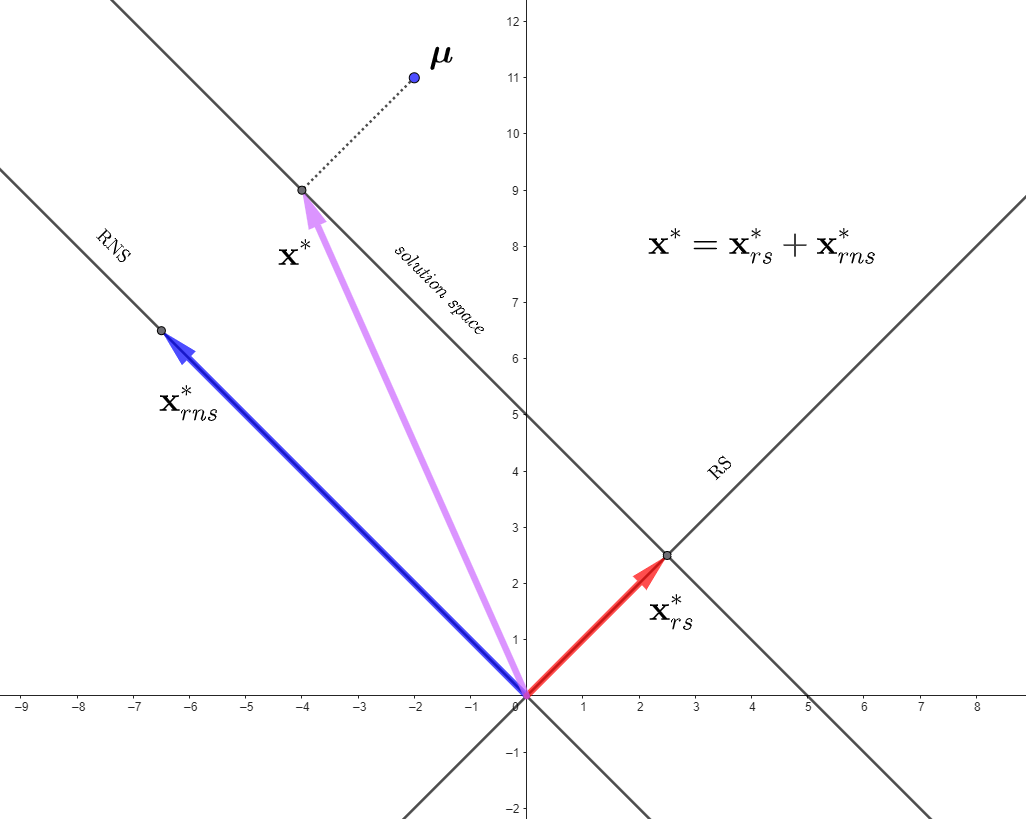

$\mathbf{\mu}=\mathbf{0}$ in the first example.

Demonstrate that if $\mathbf{\mu}$ is in the row space, the right null space component of the solution (the point projected on to the solution space is zero) $!?!?$ 

A = [1 2 3; 3 4 5];
b = [1 2]';
mu = [-2 11 2]';
x1 = (eye(3)-pinv(A)*A)*mu  + pinv(A)*b  

x1 =    -3.5000
    7.5000
   -3.5000


x2 = 2*(eye(3)-pinv(A)*A)*mu  + pinv(A)*b

x2 =    -7.1667
   14.8333
   -7.1667


A*x1

ans =     1.0000
    2.0000


A*x2

ans =     1.0000
    2.0000


norm(x1)

ans = 8.9861

norm(x2)

ans = 17.9652

# Shrinkage function

Consider the optimization problem in one variable


$$\underset{\mathbf{x}}{\mathrm{argmin}} \space$$
 
$$\|x\|_1}$$
 
$$+\frac{\rho}{2}\|x-c\|_2^2$$
                        
$$\rightarrow (1)$$


This is equivalent to finding the point where the minimum of the sum of the abs function and the quadratic function is.


$$f_1(x)=|x|$$



$$f_2(x)=\frac{\rho}{2}(x-c)^2$$


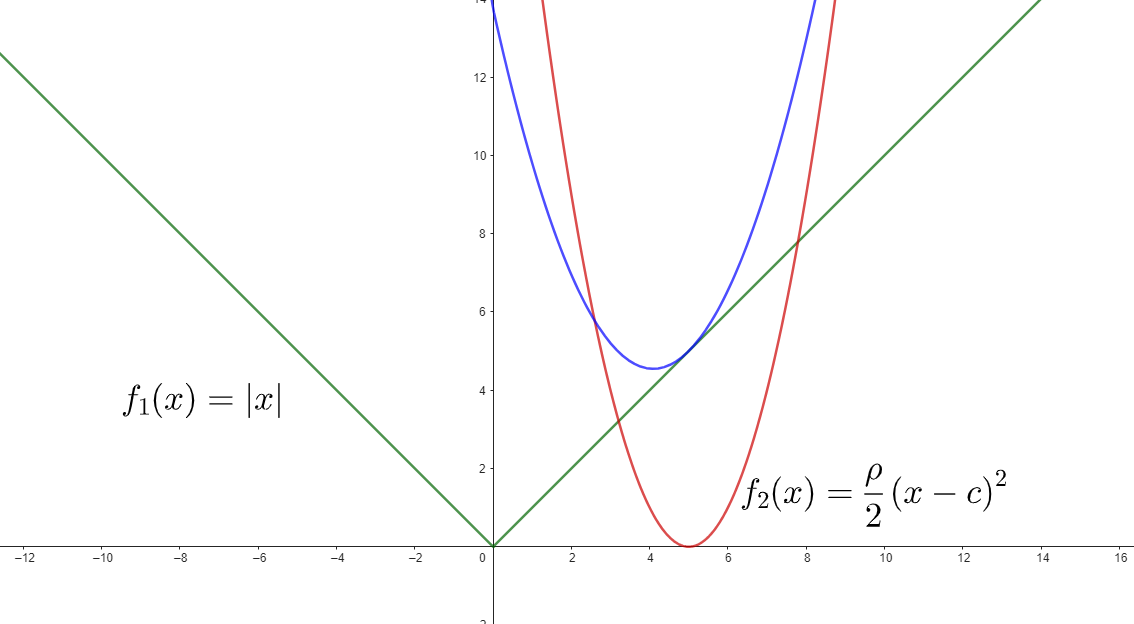

In more than one variable the equivalent form of $(1)$ is 


$$\underset{\mathbf{x}}{\mathrm{argmin}} \space {\|\mathbf{x}\|_1}$$

$$+\frac{\rho}{2}\|\mathbf{x}-\mathbf{c}\|_2^2$$



$$=\underset{\mathbf{x}}{\mathrm{argmin}}$$
 
$$\sum_1^n|x_i|+\frac{\rho}{2}\|\mathbf{x}-\mathbf{c}\|_2^2$$


Taking the derivative at $\mathbf{x} \neq 0$


$$=\mathrm{sgn}(\mathbf{x})+\rho(\mathbf{x}-\mathbf{c})=0$$


$\therefore$ $\mathbf{x}^*=\mathbf{c}-\frac{1}{\rho}\mathrm{sgn}(\mathbf{x^*})$ with shrink towards zero if $\mathrm{sgn}(\mathbf{x}) \neq \mathrm{sgn}(\mathbf{c})$

This can be rewritten as

$\mathbf{x}^*=\mathbf{c}-\frac{1}{\rho}\mathrm{sgn}(\mathbf{c})$ with shrink towards zero if $\mathrm{sgn}(\mathbf{x}) \neq \mathrm{sgn}(\mathbf{c})$

since the sign of the solution is same as that of $\mathbf{c}$.

In the case of one variable, it can be easily seen that the solution $\mathbf{x}^*$ is between $0$ and $c$ and has the same sign as $c$.

This result is used in the X update equation in the $L_1$ norm optimization using ADMM.

#### Examples for one variable case

Plot the graph for the following cases

Suppose $c=3$ and $\rho = 1$


$$x^* = c-\frac{\mathrm{sgn}(c)}{\rho}$$

$$=3-\frac{1}{1}$$

$$=2$$


Suppose $c=3$ and $\rho = 0.5$


$$x^* = c-\frac{\mathrm{sgn}(c)}{\rho}$$

$$=3-\frac{1}{0.1}$$

$$=-7\rightarrow0$$


Suppose $c=-4$ and $\rho = 0.5$


$$x^* = c-\frac{\mathrm{sgn}(c)}{\rho}$$

$$=-4-\frac{-1}{0.5}$$

$$=-2$$


Suppose $c=-3$ and $\rho = 0.25$


$$x^* = c-\frac{\mathrm{sgn}(c)}{\rho}$$

$$=-3-\frac{-1}{0.25}$$

$$=1\rightarrow0$$


#### Examples for multivariate case

Suppose $\mathbf{c}=\left[ \matrix{3 \cr 2 \cr -5 \cr 2} \right]$ and $\rho = 1$, $\mathbf{x}^*=\mathbf{c}-\frac{sgn(\mathbf{c})}{\rho}$$=\left[ \matrix{3 \cr 2 \cr -5 \cr 2} \right]$$-\left[ \matrix{1 \cr 1 \cr -1 \cr 1} \right]$$=\left[ \matrix{2 \cr 1 \cr -4 \cr 1} \right]$

Suppose $\mathbf{c}=\left[ \matrix{1 \cr 1 \cr -2 \cr 2} \right]$ and $\rho = 0.5$, $\mathbf{x}^*=\mathbf{c}-\frac{sgn(\mathbf{c})}{\rho}$$=\left[ \matrix{1 \cr 1 \cr -2 \cr 2} \right]$$-\left[ \matrix{2 \cr 2 \cr -2 \cr 2} \right]$$=\left[ \matrix{-1 \cr -1 \cr 0 \cr 0} \right]$$\rightarrow$$\left[ \matrix{0 \cr 0 \cr 0 \cr 0} \right]$

Suppose $\mathbf{c}=\left[ \matrix{4 \cr 0.5 \cr -2 \cr 5} \right]$ and $\rho = 0.5$, $\mathbf{x}^*=\mathbf{c}-\frac{sgn(\mathbf{c})}{\rho}$$=\left[ \matrix{4 \cr 0.5 \cr -2 \cr 5} \right]$$-\left[ \matrix{2 \cr 2 \cr -2 \cr 2} \right]$$=\left[ \matrix{2 \cr -1.5 \cr 0 \cr 3} \right]$$\rightarrow$$\left[ \matrix{2 \cr 0 \cr 0 \cr 3} \right]$

# Basis Pursuit

(shrinkage, projection, gradient)

$\underset{\mathbf{x}}{\mathrm{argmin}} \space \|\mathbf{x}\|_1$ subject to the constraints$A\mathbf{x}=\mathbf{b}$ 

In pursuit of a sparse basis

Finding the least $\ell_1$ norm solution to $A\mathbf{x}=\mathbf{b}$ is called basis pursuit because the method seeks to find a small subset of columns from the matrix $A$ (the "basis") that can be used to represent the vector b. The term "pursuit" refers to the optimization process that "pursues" a sparse solution.

$\ell_1$-Norm and Sparsity

 The $\ell_1$-norm of a vector is the sum of the absolute values of its elements. When you minimize the $\ell_1$-norm of a vector $\mathbf{x}$ subject to the constraint $A\mathbf{x}=\mathbf{b}$, you are encouraging sparse solution. A sparse solution is one where most of the elements of `x` are zero.

Basis Selection

 The equation $A\mathbf{x}=\mathbf{b}$ can be seen as a linear combination of the columns of $A$, where the coefficients of the combination are the elements of $\mathbf{x}$. If $\mathbf{x}$ is sparse, it means that only a few of its elements are non-zero. These non-zero elements correspond to the columns of $A$ that are actively used to form $\mathbf{b}$. In essence, the optimization process is selecting a small "basis" of vectors from the columns of $A$.

"Pursuit"

 The "pursuit" part of the name refers to the algorithmic process of searching for this sparse basis among all the possible combinations of columns in $A$.

#### $L_1$ norm optimization problem using ADMM

#### Least $L_1$ norm solution to $A\mathbf{x} =\mathbf{b}$

#### $\underset{\mathbf{x}}{\mathrm{argmin}} \space \|\mathbf{x}\|_1$ subject to the constraints$A\mathbf{x}=\mathbf{b}$        $\rightarrow (1)$

To convert this problem to ADMM format

Assume $f(\mathbf{x})=\|\mathbf{x}\|_1$ and $g(\mathbf{z})=0$ if $A\mathbf{z}=\mathbf{b}$; $\infty$ if $A\mathbf{z} \neq \mathbf{b}$               $\rightarrow (2)$         Indicator function

Write the simplified augmented lagrangian function can be written


$$L_\rho(\mathbf{x},\mathbf{z},\mathbf{u})=\|\mathbf{x}\|_1+g(\mathbf{z})+\frac{\rho}{2}\|\mathbf{x}-\mathbf{z}+\mathbf{u}\|_2^2$$
                                                    
$$\rightarrow (3)$$


Write the update equations for the variables $\mathbf{x},\mathbf{z}$ and $\mathbf{u}$.


$$\mathbf{x}^{(k+1)}=$$

$$\underset{\mathbf{x}}{\mathrm{argmin}}$$

$$L_\rho(\mathbf{x},\mathbf{z}^{(k)},\mathbf{u}^{(k)})=$$
 
$$\underset{\mathbf{x}}{\mathrm{argmin}}$$

$$\space \|\mathbf{x}\|_1$$
 
$$+\frac{\rho}{2}\|\mathbf{x}-\mathbf{z}^{(k)}+\mathbf{u}^{(k)}\|_2^2$$
                      
$$\rightarrow (4)$$


        Using shrinkage function, update $\mathbf{x}$.

        The vertex of the parabola in $(4)$ is at $\mathbf{c} =\mathbf{z}^{(k)}-\mathbf{u}^{(k)}$ 

        The updated $\mathbf{x}$ is obtained using the shrinkage function discussed in the previous section.

        $\mathbf{x}^{(k+1)}=\mathbf{c}-\frac{1}{\rho}sgn(\mathbf{c})$ and shrink towards zero


$$\mathbf{z}^{(k+1)}=$$

$$\underset{\mathbf{z}}{\mathrm{argmin}}\space$$

$$L_\rho(\mathbf{x}^{(k+1)},\mathbf{z},\mathbf{u}^{(k)})=$$
 
$$\underset{\mathbf{z}}{\mathrm{argmin}}$$
 
$$\space g(\mathbf{z})$$
 
$$+\frac{\rho}{2}\|\mathbf{x}^{(k+1)}-\mathbf{z}+\mathbf{u}^{(k)}\|_2^2$$
                      
$$\rightarrow (5)$$


        Using projection of $\mathbf{x}^{(k+1)}+\mathbf{u}^{(k)}}$ on to $A\mathbf{z} = \mathbf{b}$,  update $\mathbf{z}$.

        The updated $\mathbf{z}$ is obtained by projecting $\mathbf{x}^{(k+1)}+\mathbf{u}^{(k)}}$ on $A\mathbf{z} = \mathbf{b}$. 

        We will use the result from the section "Projection"

        
$$\mathbf{\mu}=\mathbf{x}^{(k+1)}+\mathbf{u}^{(k)}}$$


        
$$\mathbf{z}^{(k+1)}=$$

$$(I-A^T(AA^T)^{-1}A)\mathbf{\mu}$$
 
$$+A^T(AA^T)^{-1}\mathbf{b}$$


        
$$\mathbf{z}^{(k+1)}=$$

$$(I-A^\dagger A)\mathbf{\mu}$$
 
$$+A^\dagger\mathbf{b}$$



$$\mathbf{u}^{(k+1)}=$$

$$\mathbf{u}^{(k)}$$

$$+(\mathbf{x}^{(k+1)}-\mathbf{z}^{(k+1)})$$
                                                                                      
$$\rightarrow (6)$$


Using gradient, update $\mathbf{u}$.

Repeat the iteration until the desired precision is obtained.

# $L_1$ norm optimized solution for Linear Programming 

$\underset{\mathbf{x}}{\mathrm{argmin}} \space \|\mathbf{x}\|_1$ subject to the constraints$A\mathbf{x}=\mathbf{b}$        $\rightarrow (1)$

Let $\mathbf{x}=\mathbf{x}_1-\mathbf{x}_2$                                 $\rightarrow (2)$

such that $\|\mathbf{x}\|_1=\|\mathbf{x}_1\|_1+\|\mathbf{x}_2\|_1$          $\rightarrow (3)$

and $\mathbf{x}_{1,2} \geq \mathbf{0}$                                         $\rightarrow (4)$


$$A\mathbf{x}=A(\mathbf{x}_1-\mathbf{x}_2)$$
 
$$= A\mathbf{x}_1-A\mathbf{x}_2=$$

$$\left[\matrix{A & -A}\right] \left[\matrix{\mathbf{x}_1 \cr \mathbf{x}_2}\right]=$$

$$B\mathbf{z}=\mathbf{b}$$
         
$$\rightarrow (5)$$


where $B=\left[\matrix{A & -A}\right]$                                                                  $\rightarrow (6)$

and 


$$\mathbf{z} =  \left[\matrix{\mathbf{x}_1 \cr \mathbf{x}_2}\right]$$
                                                                                     
$$\rightarrow (7)$$


Now 


$$\|\mathbf{x}\|_1 = \sum_{i=1}^{n}\mathbf{x}_{1i}+\mathbf{x}_{2i}$$

$$=\mathbf{e}^T\mathbf{z}$$
                                                          
$$\rightarrow (8)$$


where $\mathbf{e}=\left[ \matrix{1 & \cdots & 1}\right]^T$                                                                  $\rightarrow (9)$

is a constant vector of all ones.

Now the optimization problem in $(1)$ can be recast as a linear programming problem as 

$\underset{\mathbf{z}}{\mathrm{argmin}}\space$ $\mathbf{e}^T\mathbf{z}$ subject to the constraints $B\mathbf{z}=\mathbf{b}$ and $\mathbf{z} \geq 0$

# Linear Programming with equality constraints using ADMM

$\underset{\mathbf{x}}{\mathrm{argmin}}\space$ $\mathbf{c}^T\mathbf{x}$ subject to the constraints $A\mathbf{x}=\mathbf{b}$ and $\mathbf{x} \ge 0$

Define $f(\mathbf{x})=\mathbf{c}^T\mathbf{x}$ with $A\mathbf{x}=\mathbf{b}$

and $g(\mathbf{z})=0$ if $\mathbf{z} \ge 0$ and $\infty$ if $\mathbf{z} \lt 0$                (Indicator function)

The Lagrangian is 


$$L(\mathbf{x},\mathbf{z},\mathbf{\lambda})=$$

$$f(\mathbf{x})+g(\mathbf{z})+\mathbf{\lambda^T}\mathbf{(x-z)}$$


The augmented Lagrangian is 


$$L(\mathbf{x},\mathbf{z},\mathbf{\lambda})=$$

$$f(\mathbf{x})+g(\mathbf{z})+\mathbf{\lambda^T}\mathbf{(x-z)}$$

$$+\frac{\rho}{2}\|\mathbf{x}-\mathbf{z}\|_2^2$$


The simplified augmented Lagrangian function is

$L_\rho(\mathbf{x},\mathbf{z},\mathbf{u})=$$f(\mathbf{x}) + g(\mathbf{z}) + \frac{\rho}{2}\|\mathbf{x}-\mathbf{z}+\mathbf{u}\|_2^2$ (after assuming initial values for z and u vector)

We find the minimum of this simplified augmented Lagrangian function numerically.

Write the update equations for the variables $\mathbf{x},\mathbf{z}$ and $\mathbf{u}$.


$$\mathbf{x}^{(k+1)}=$$

$$\underset{\mathbf{x}}{\mathrm{argmin}}$$

$$L_\rho(\mathbf{x},\mathbf{z}^{(k)},\mathbf{u}^{(k)})=$$
 
$$\underset{\mathbf{x}}{\mathrm{argmin}}$$

$$\space f(\mathbf{x})$$
 
$$+\frac{\rho}{2}\|\mathbf{x}-\mathbf{z}^{(k)}+\mathbf{u}^{(k)}\|_2^2$$
                      
$$\rightarrow (4)$$



$$L_\rho(\mathbf{x},\mathbf{\lambda})=$$
 
$$\mathbf{c}^T\mathbf{x}+\mathbf{\eta}^T(A\mathbf{x}-\mathbf{{b})$$

$$+\frac{\rho}{2}\|\mathbf{x}-\mathbf{z}^{(k)}+\mathbf{u}^{(k)}\|_2^2$$
                                                     
$$\rightarrow (5)$$



$$\frac{\partial L_\rho}{\partial \mathbf{x}}=$$

$$\mathbf{c} + A^T\mathbf{\eta} + \rho(\mathbf{x}-\mathbf{z}^{(k)}+\mathbf{u}^{k})=\mathbf{0}$$
                                                                         
$$\rightarrow (6)$$



$$\frac{\partial L_\rho}{\partial \mathbf{\lambda}}=A\mathbf{x}-\mathbf{b}=\mathbf{0}$$
                                                                                                     
$$\rightarrow (7)$$


Eq:s $(5)$ and $(6)$ can be combined as below


$$\left[\matrix{\rho I_{n \times n} & A^T \cr A & 0_{m \times m}}\right] \left[\matrix{\mathbf{x} \cr \mathbf{\eta}}\right] =$$
 
$$\left[\matrix{\rho(\mathbf{z}^{(k)}-\mathbf{u}^{(k)})-\mathbf{c} \cr \mathbf{b}}\right]$$
                                                                              
$$\rightarrow (8)$$


The solution to this can be found by inverting the square matrix (of size $(m+n) \times (m+n)$) on the left side of eq $(8)$.

This gives $\mathbf{x}^{(k+1)}$. Before iterating, we can compute the inverse of this matrix and use it repeatedly as this matrix is not constant.


$$\mathbf{z}^{(k+1)}=$$

$$\underset{\mathbf{x}}{\mathrm{argmin}}$$

$$L_\rho(\mathbf{x}^{(k+1)},\mathbf{z},\mathbf{u}^{(k)})=$$
 
$$\underset{\mathbf{x}}{\mathrm{argmin}}$$
 
$$\space g(\mathbf{z})$$
 
$$+\frac{\rho}{2}\|\mathbf{x}^{(k+1)}-\mathbf{z}+\mathbf{u}^{(k)}\|_2^2$$
                      
$$\rightarrow (9)$$


Using projection of $\mathbf{x}^{(k+1)}+\mathbf{u}^{(k)}}$ on to $R_+$,  update $\mathbf{z}$.


$$\mathbf{z}^{(k+1)}=|\mathbf{x}^{(k+1)}+\mathbf{u}^{(k)}|_{R_+}$$



$$\mathbf{u}^{(k+1)}=$$

$$\mathbf{u}^{(k)}$$

$$+(\mathbf{x}^{(k+1)}-\mathbf{z}^{(k+1)})$$
                                                                                      
$$\rightarrow (10)$$


Using gradient, update $\mathbf{u}$.

# Mapping LP with inequality constraints to LP with equality constraints

$\underset{\mathbf{y}}{\mathrm{argmin}}\space$ $\mathbf{c}^T\mathbf{y}$ subject to the constraints $M\mathbf{y}\leq \mathbf{b}$ and $\mathbf{y} \ge \mathbf{0}$

where $\mathbf{c},\mathbf{y} \in R^n$, $\mathbf{b} \in R^m$ and $M \in R^{m \times n}$

To remove the inequality we introduce a slack variable $\mathbf{u} \in R^m$ where $\mathbf{u} \geq \mathbf{0}$.


$$M\mathbf{y}+I\mathbf{u} =\mathbf{b}$$



$$\left[\matrix{M & I}\right]\left[\matrix{\mathbf{y} \cr \mathbf{u}}\right]=\mathbf{b}$$


The objective function and the constraints are transformed as below.

The $m$ (equations) constraints in $n$ unknowns (initially $\mathbf{y}$) is changed to $m$ constraints in $n+m$ unknowns $\mathbf{x}=\left[ \matrix{\mathbf{y} \cr \mathbf{u}} \right]$

$\mathbf{y} \in R^n$ $\rightarrow$ $\mathbf{x}=\left[ \matrix{\mathbf{y} \cr \mathbf{u}} \right] \in R^{m+n}$, $\mathbf{y},\mathbf{u} \geq \mathbf{0}$

The corresponding coefficient matrix $M$ is changed to $A = \left[ \matrix{M_{m\times n} & I_{m \times m}}\right]$


$$M \in R^{m\times n}$$
 
$$\rightarrow$$
 
$$A = \left[ \matrix{M_{m\times n} & I_{m \times m}}\right] \in R^{m \times (m+n)}$$


The constant vector $\mathbf{c}$ is changed to $\mathbf{a} = \left[\matrix{ \mathbf{c}_{n\times 1} \cr \mathbf{0}_{m \times 1}}\right]$

The new optimization problem is 

$\underset{\mathbf{x}}{\mathrm{argmin}} \space \mathbf{a}^T\mathbf{x}$ subject to the constraints $A\mathbf{x} = \mathbf{b}$ and $\mathbf{x} \geq \mathbf{0}$

# Least Absolute Deviation (LAD)

$\underset{\mathbf{x,z}}{\mathrm{argmin}}\space \|\mathbf{z}\|_1$ subject to the constraints $A\mathbf{x} -\mathbf{b}=\mathbf{z}$

Note the constraint here is not $\mathbf{x}-\mathbf{z}=\mathbf{0}$, Instead it is $A\mathbf{x} -\mathbf{b}=\mathbf{z}$

The Lagrangian is


$$L=\|\mathbf{z}\|_1 + \mathbf{\lambda}^T(A\mathbf{x}-\mathbf{b}-\mathbf{z}^{(k)})$$

$$+\frac{\rho}{2}\|A\mathbf{x}-\mathbf{b}-\mathbf{z}^{(k)}\|_2^2$$


The update equation for $\mathbf{x},\mathbf{z}$ and $\mathbf{\lambda}$ are :

 
$$\mathbf{x}^{(k+1)} = \underset{\mathbf{x}}{\mathrm{argmin}} \space L(\mathbf{x},\mathbf{z}^{(k)},\mathbf{\lambda}^{(k)})$$



$$\Rightarrow A^T\mathbf{\lambda}^{(k)}+\rho A^T(A\mathbf{x}-\mathbf{b}-\mathbf{z}^{(k)})=\mathbf{0}$$



$$\Rightarrow \rho A^TA\mathbf{x} = \rho A^T(\mathbf{b}+\mathbf{z}^{(k)})-A^T\mathbf{\lambda}^{(k)}$$



$$\therefore \mathbf{x}^{(k+1)}=$$

$$(A^TA)^{-1}\left( A^T\left(\mathbf{b}+\mathbf{z}^{(k)}\right)-\frac{A^T\mathbf{\lambda}^{(k)}}{\rho}\right)$$



$$\mathbf{z}^{(k+1)}=\underset{\mathbf{z}}{\mathrm{argmin}}\space L(\mathbf{x}^{(k+1)},\mathbf{z},\mathbf{\lambda}^{(k)})$$



$$=\underset{\mathbf{z}}{\mathrm{argmin}} \space \|\mathbf{z}\|_1+$$

$$\mathbf{\lambda}^{(k)T}(A\mathbf{x}^{(k+1)}-\mathbf{b}-\mathbf{z})$$

$$+\frac{\rho}{2}\|A\mathbf{x}^{(k+1)}-\mathbf{b}-\mathbf{z}\|_2^2$$


Since this Lagrangian function involves the sum of absolute function and a quadratic function,

the solution can be obtained by using the shrinkage function discussed above. Find the vertex of the quadratic term by simplyfing the lagrangian and the augmented lagrangian terms.


$$\mathbf{\lambda}^{(k+1)}=\mathbf{\lambda}^{(k)}+(A\mathbf{x}^{(k+1)}-\mathbf{b}-\mathbf{z}^{(k+1)})$$


$\underset{\mathbf{x,z}}{\mathrm{argmin}}$$\|\mathbf{z}\|_2^2$ subject to the constraints  $A\mathbf{x} -\mathbf{b}=\mathbf{z}$, $\mathbf{z}$ is the error vector.

$\underset{\mathbf{x,z}}{\mathrm{argmin}}$$\|\mathbf{z}\|_1$ subject to the constraints  $A\mathbf{x} -\mathbf{b}=\mathbf{z}$, $\mathbf{z}$ is the error vector.

#### Exercise

$\underset{\mathbf{x}}{\mathrm{argmin}} \space \|\mathbf{x}\|_1$ subject to the constraint $2x_1+3x_2=4$

$\underset{\mathbf{x}}{\mathrm{argmin}} \space \|\mathbf{x}\|_1$ subject to the constraints $2x_1+3x_2-x_3=4$ and  $2x_1-3x_2-x_3=1$

#### Coding exercises - 09-July-2025

Write Matlab/Octave function to compute

- $L_0,L_1,L_2,L_\infty$ norm of given vectors

- Shrinkage function

- Projection

- Least $L_1$ norm solution to $A\mathbf{x} = \mathbf{b}$ using ADMM

- Least $L_2$ norm solution to $A\mathbf{x} = \mathbf{b}$

- closest point to origin on the plane $A\mathbf{x}=\mathbf{b}$

- closest point to $\mathbf{\mu}$ on the plane $A\mathbf{x}=\mathbf{b}$

- LP with equality

function name : L1norm

input : a vector

output : $L_1$ norm of the input vector

Logic : sum of absolute values of the components of the input vector

function name : L2norm

input : a vector

output : $L_2$ norm of the input vector

function name : L0norm

input : a vector

output : $L_0$ norm of the vector

function result = L1norm(x)

x =     -3     4     0


    result = sum(abs(x));

ans = 2

end

ans = 7

ans = 5

function result = L2norm(x)

ans = 4

    result = sqrt(sum(x.^2));
end

function result = L0norm(x)
    result = sum(abs(x)>0);
end

function result = LInfnorm(x)
    result = max(abs(x));
end

outfile = "/media/user/DATA4LINUX/new1/Repos/Mine/MFC4_22MAT230/U1_Optimization_Lagrangian_ADMM_v6.mlx.pdf"

x=[-3 4 0]
L0norm(x)
L1norm(x)
L2norm(x)
LInfnorm(x)

#### References

[https://en.wikipedia.org/wiki/Augmented_Lagrangian_method#Alternating_direction_method_of_multipliers](https://en.wikipedia.org/wiki/Augmented_Lagrangian_method#Alternating_direction_method_of_multipliers)

[https://en.wikipedia.org/wiki/Quadratic_programming](https://en.wikipedia.org/wiki/Quadratic_programming)

[https://en.wikipedia.org/wiki/Total_variation_denoising](https://en.wikipedia.org/wiki/Total_variation_denoising)

[https://developers.google.com/optimization/introduction](https://developers.google.com/optimization/introduction)

[https://developers.google.com/optimization/introduction](https://developers.google.com/optimization/introduction)

cd("/media/user/DATA4LINUX/new1/Repos/Mine/MFC4_22MAT230/")
mlxfile = matlab.desktop.editor.getActive().Filename;
outfile = mlxfile + ".pdf";
export(matlab.desktop.editor.getActive().Filename, outfile);